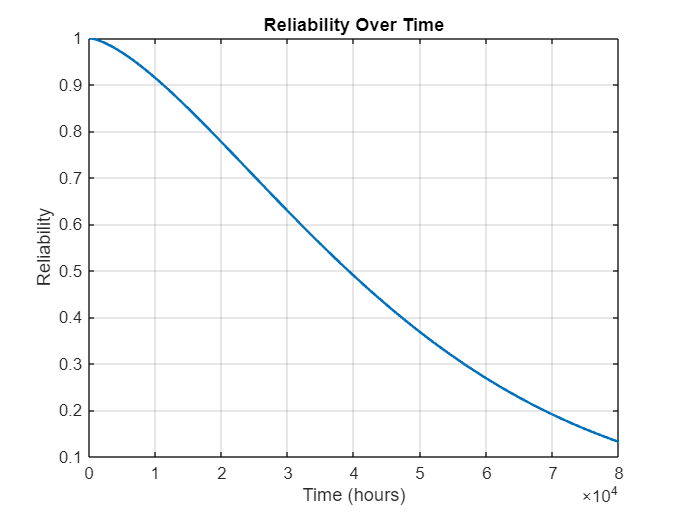

% Weibull Parameters
eta = 50000;    % Characteristic life (scale parameter)
beta = 1.5;     % Shape parameter

% Time vector (hours)
t = 0:1000:80000;

% Reliability Function R(t)
Reliability = exp(-(t./eta).^beta);

% Failure Probability P(t)
FailureProbability = 1 - Reliability;

% Probability Density Function (PDF) f(t)
PDF = (beta/eta) * (t./eta).^(beta - 1) .* exp(-(t./eta).^beta);

% Failure Rate Function λ(t)
FailureRate = (beta/eta) * (t./eta).^(beta - 1);

% Plot Reliability Over Time
figure;
plot(t, Reliability, 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Reliability');
title('Reliability Over Time');
grid on;

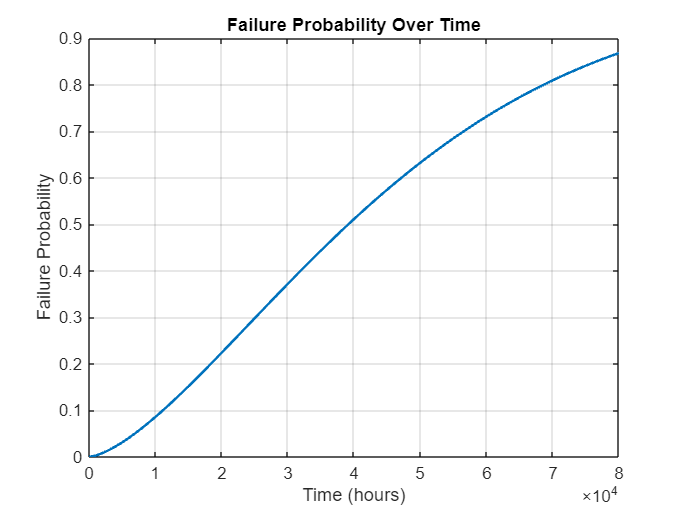


% Plot Failure Probability Over Time
figure;
plot(t, FailureProbability, 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Failure Probability');
title('Failure Probability Over Time');
grid on;

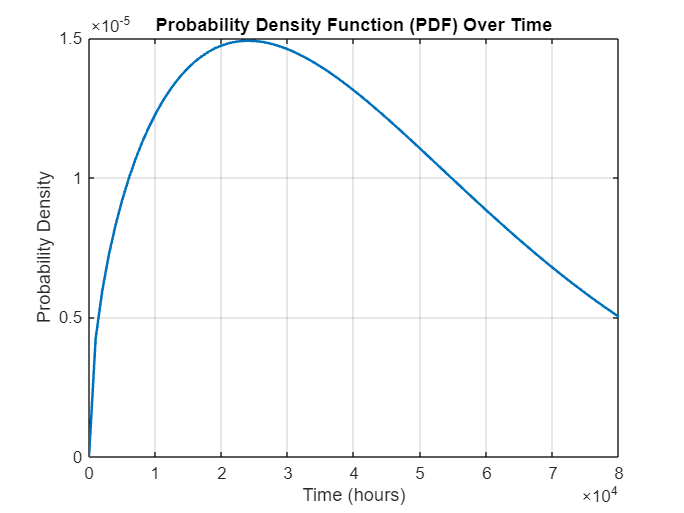


% Plot Probability Density Function (PDF) Over Time
figure;
plot(t, PDF, 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Probability Density');
title('Probability Density Function (PDF) Over Time');
grid on;

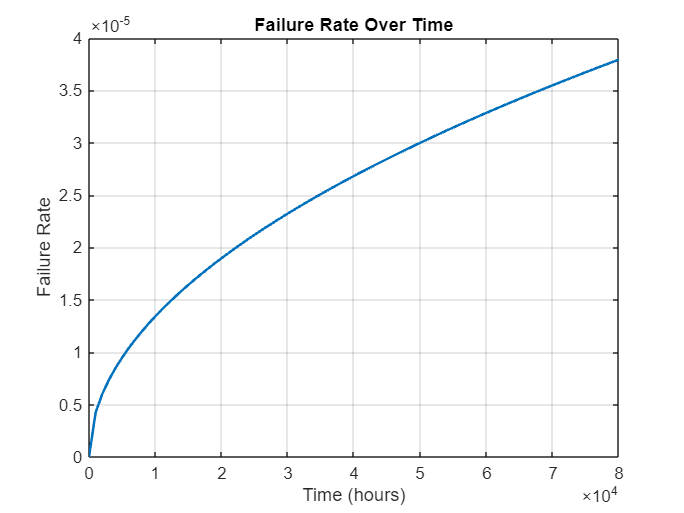


% Plot Failure Rate Over Time
figure;
plot(t, FailureRate, 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Failure Rate');
title('Failure Rate Over Time');
grid on;